Question 1

L = 1000 ;
X = (1:L);
D = randi([0 1],L,1);       %generating a random binary sequence of length 1000

%generating a rectangular pulse S
A = 1;
S = zeros(1,L) ;            %generating a zero sequence of length L
for n = 1:L 
    if D(n) == 0 
        S(n) = (-1)*A;      %assigning -A if D(n) equals zero
    else
        S(n) = A ;          %assigning A if D(n) equals one
    end
end

Question 2

mean = 0 ;
var = 1 ;
N = mean + var* randn(1,L);   %generating AWGN with zero mean and variance sigma

Question 3

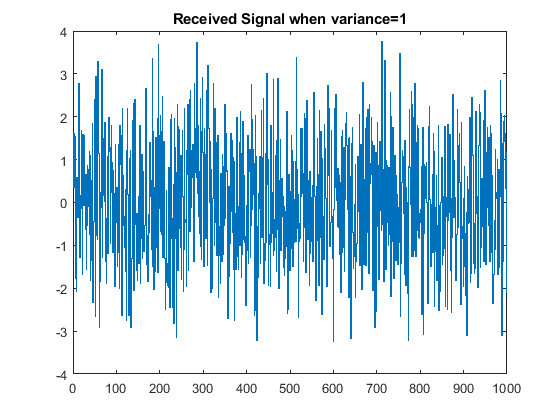

R = S + N  ;                  %generating received signal

%plotting the received signal when variance=1
figure;
stairs(X,R);
title("Received Signal when variance=1");

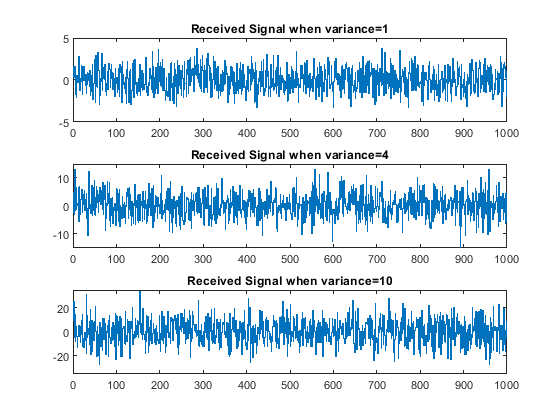

%generating the received signal when variance=4
var1 = 4 ;
N1 = mean + var1* randn(1,L);
R1 = S + N1  ; 

%generating the received signal when variance=10
var2 = 10 ;
N2 = mean + var2* randn(1,L);
R2 = S + N2 ;

%plotting the graphs
figure;
subplot(3,1,1);
stairs(X,R);
title("Received Signal when variance=1");
subplot(3,1,2);
stairs(X,R1);
ylim([-15,15]);
title("Received Signal when variance=4");
subplot(3,1,3);
stairs(X,R2);
ylim([-35,35]);
title("Received Signal when variance=10");

By oberserving the above three plots of received signal with noise variance 1,4 and 10, we can conclude that; when the variance is increased the amplitude of received signal also increases. So the signal get more distorted.